IMUData = readtable('10s_500Hz_20pp_z_axis.csv');
X_acc = IMUData{:, 2};
Y_acc = IMUData{:, 3};
Z_acc = IMUData{:, 4};
roll = IMUData{:, 5};
pitch = IMUData{:, 6};
yaw = IMUData{:, 7};

Fs = 500;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = height(IMUData(:, 4));             % Length of signal
t = (0:L-1)*T;        % Time vector

%Z_acc calculations

%Z_acc_ms2 = highpass(Z_acc, 0.03, Fs)
a = 0.01

a = 0.0100

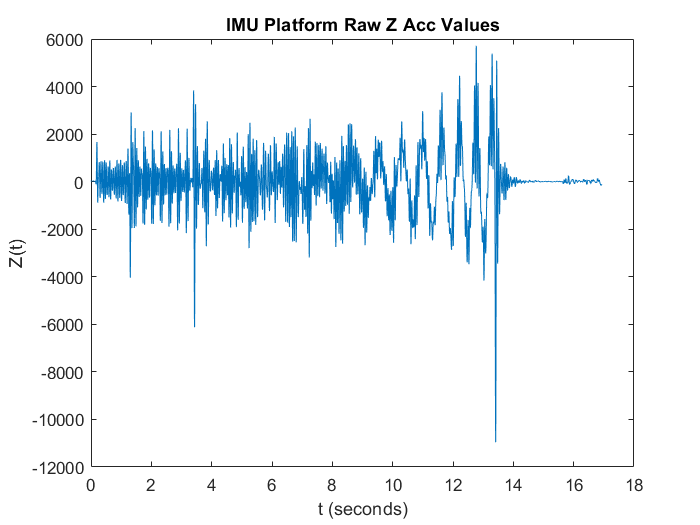

Z_acc_wave = transpose(diff(diff(a*sin(t))));
t = t;
Z_acc = Z_acc;
Z_acc = detrend(Z_acc);

Z_acc = lowpass(Z_acc, 1, Fs);
Z_acc_ms2 = Z_acc/16381.0; 

Z_velocity_uncalibrated = cumtrapz(Z_acc_ms2);

Z_position_uncalibrated = cumtrapz(Z_velocity_uncalibrated);

Z_acc_ms2_calibrated = ((Z_acc-92.2236)/(1686.46*9.81722));

Z_velocity_calibrated = cumtrapz(detrend(Z_acc_ms2_calibrated));

Z_position_calibrated = cumtrapz((Z_velocity_calibrated));

Z_position_fft = acc2disp(Z_acc, T);

plot(t, Z_acc)
title('IMU Platform Raw Z Acc Values')
xlabel('t (seconds)')
ylabel('Z(t)')

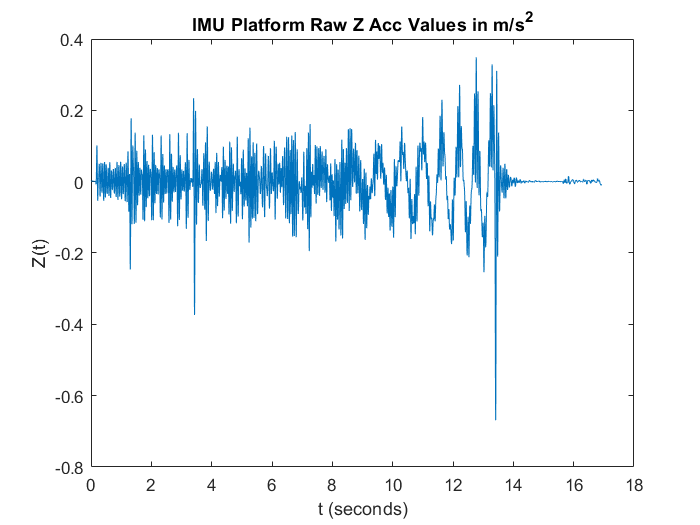


plot(t, Z_acc_ms2)
title('IMU Platform Raw Z Acc Values in m/s^2')
xlabel('t (seconds)')
ylabel('Z(t)')

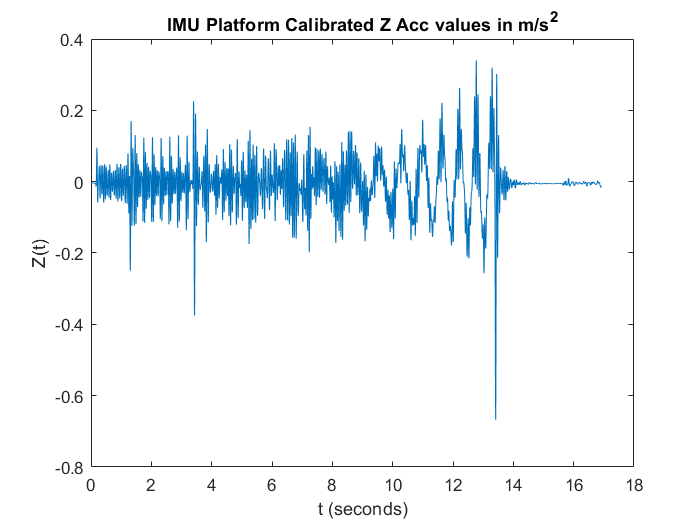


plot(t, Z_acc_ms2_calibrated)
title('IMU Platform Calibrated Z Acc values in m/s^2')
xlabel('t (seconds)')
ylabel('Z(t)')

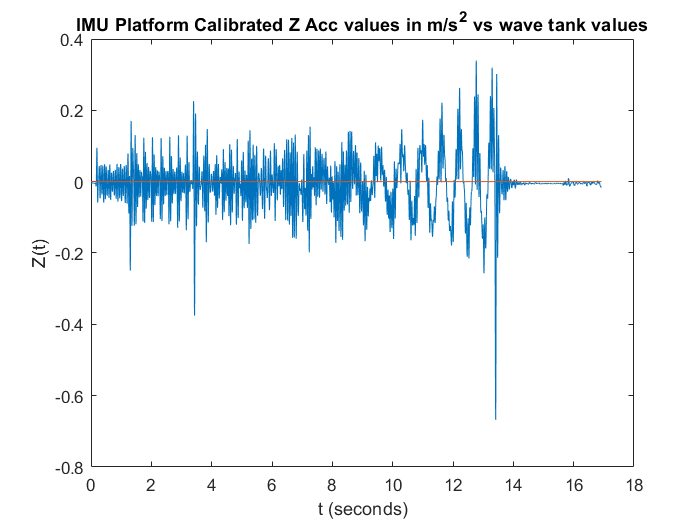


plot(t(1, 1:8462), Z_acc_ms2_calibrated(1:8462, 1), t(1, 1:8462), Z_acc_wave(1:8462, 1));
title('IMU Platform Calibrated Z Acc values in m/s^2 vs wave tank values')
xlabel('t (seconds)')
ylabel('Z(t)')

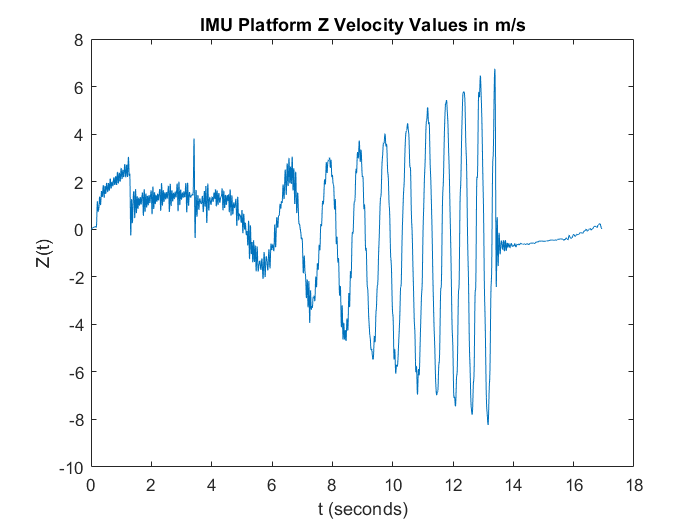



plot(t, Z_velocity_uncalibrated)
title('IMU Platform Z Velocity Values in m/s')
xlabel('t (seconds)')
ylabel('Z(t)')

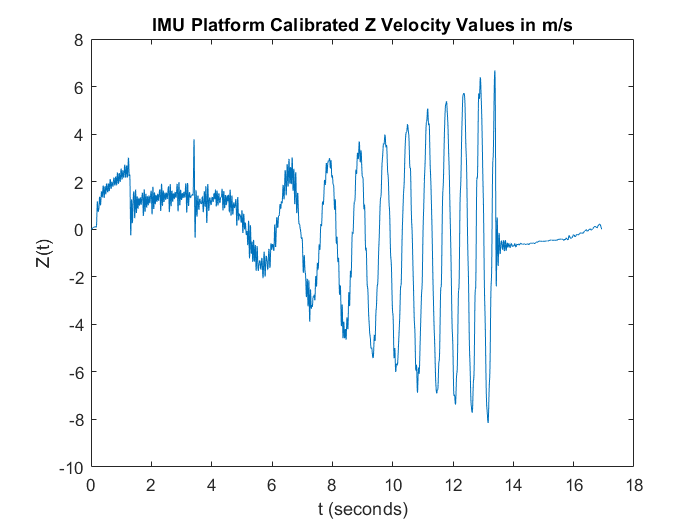


plot(t, Z_velocity_calibrated)
title('IMU Platform Calibrated Z Velocity Values in m/s')
xlabel('t (seconds)')
ylabel('Z(t)')

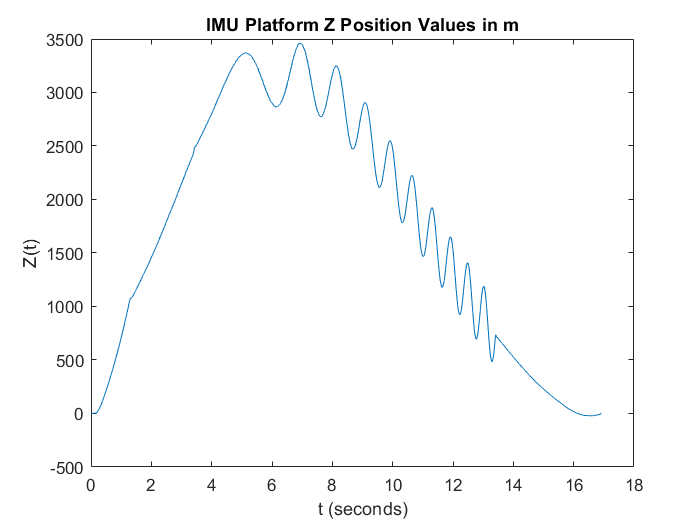


plot(t, Z_position_uncalibrated)
title('IMU Platform Z Position Values in m')
xlabel('t (seconds)')
ylabel('Z(t)')

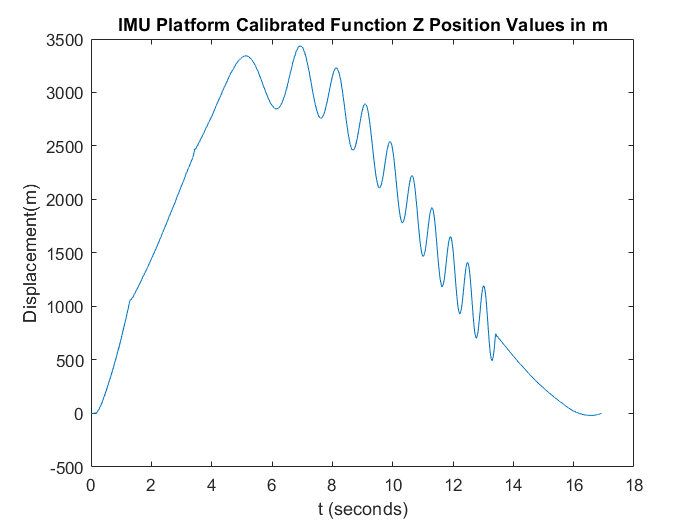


plot(t, Z_position_calibrated)
title('IMU Platform Calibrated Function Z Position Values in m')
xlabel('t (seconds)')
ylabel('Displacement(m)')

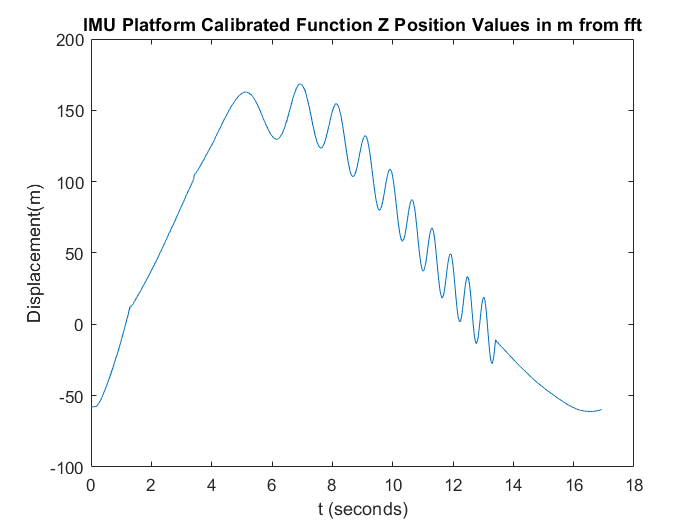


plot(t, Z_position_fft)
title('IMU Platform Calibrated Function Z Position Values in m from fft')
xlabel('t (seconds)')
ylabel('Displacement(m)')

function disp_time_data = acc2disp(acc_time_data,dt)
% acc_time_data should be acceleration amplitudes evenly spaced in time
% dt in units of seconds per sample
N1 = length(acc_time_data);
  N = 2^nextpow2(N1);
  if N > N1
      acc_time_data(N1+1:N) = 0; % pad array with 0's
  end
  df = 1 / (N*dt); % frequency increment
  Nyq = 1 / (2*dt); % Nyquist frequency
  acc_freq_data = fftshift(fft(acc_time_data));
  disp_freq_data = zeros(size(acc_freq_data));
  f = -Nyq:df:Nyq-df; % I think this is how fftshift organizes it
  for i = 1 : N
      if f(i) ~= 0
          disp_freq_data(i) = acc_freq_data(i)/(2*pi*f(i)*sqrt(-1))^2;
      else
          disp_freq_data(i) = 0;
      end
  end
  disp_time_data = ifft(ifftshift(disp_freq_data));    
  disp_time_data = disp_time_data(1:N1);
return

end